# **PROJECT #2 (Contd.)**

**ENPM 667 : CONTROL OF ROBOTIC SYSTEMS**

**NAME : ADITYA VAISHAMPAYAN (116077354), ABHISHEK KATHPAL (114852373)**

**EMAIL ID:adityav@terpmail.umd.edu, akathpal@umd.edu**

**CONTACT NO: +1-240-743-0530**

## **F) LUENBERGER OBSERVER**

M = 1000;
m1 = 100;
m2 = 100;
l1 = 20;
l2 = 10;
g = 9.8;

A = [0  1      0            0       0           0;
     0  0   (-m1*g)/M       0   (-m2*g)/M       0;
     0  0      0            1       0           0;
     0  0   (-(m1+M)*g)/(M*l1)  0   (-m2*g)/(M*l1)  0;
     0  0      0            0       0           1;
     0  0   (-m1*g)/(M*l2)  0   (-(m2+M)*g)/(M*l2)  0];
 B = [0;
    (1/M);
     0;
    (1/(M*l1));
     0;
    (1/(M*l2))];

% initial state of the system
X0 = [0;0;pi/20;0;pi/40;0];
%  we take time t from 1 to 5 seconds
t = 0:0.01:5;
u = zeros(size(t));

###         i) Position of the desired poles

new_poles = [-2.1 -2.32 -2.4 -2.6 -2.8 -3];

###         ii) Applying Luenberger Gain for cart position only

%just cart position X
C = [1 0 0 0 0 0];
L = place(A',C',new_poles)';
luenberger_gain = L

luenberger_gain =    15.2200
   94.6310
 -952.3257
   48.1280
  647.1342
 -514.4996


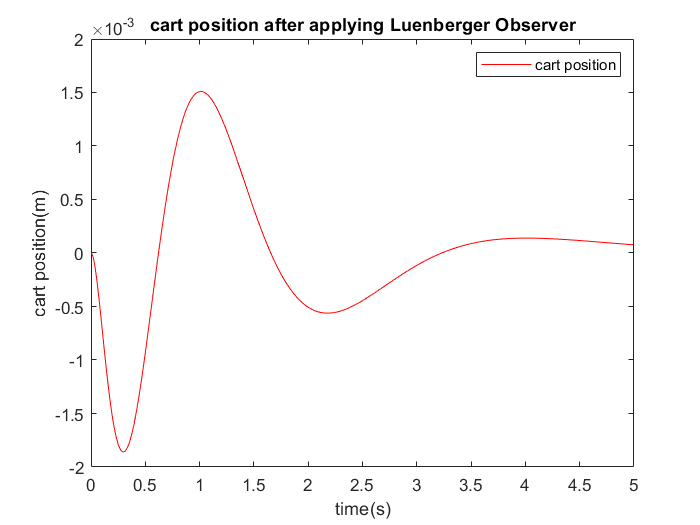

Ac = A - L*C;
Bc = [0;0;0;0;0;0];
Cc = C;
Dc = 0;
closed_loop_sys = ss(Ac,Bc,Cc,Dc);
[y,t,~] = lsim(closed_loop_sys,u,t,X0);

%plotting the graph for cart position after applying luenberger observer
plot(t,y(:,1),'red')
title('cart position after applying Luenberger Observer')
xlabel('time(s)')
ylabel('cart position(m)')
legend('cart position')

###         iii) Applying Luenberger gain for cart position and angular position of mass 2 

%cart position X and theta2
C = [1 0 0 0 0 0; 0 0 0 0 1 0];
L = place(A',C',new_poles)';
luenberger_gain=L

luenberger_gain =     9.3414    7.5441
   31.8531   55.1943
  -45.3029 -136.8503
  -11.0742  -83.7411
    0.4233    5.8786
    2.5376   11.0571


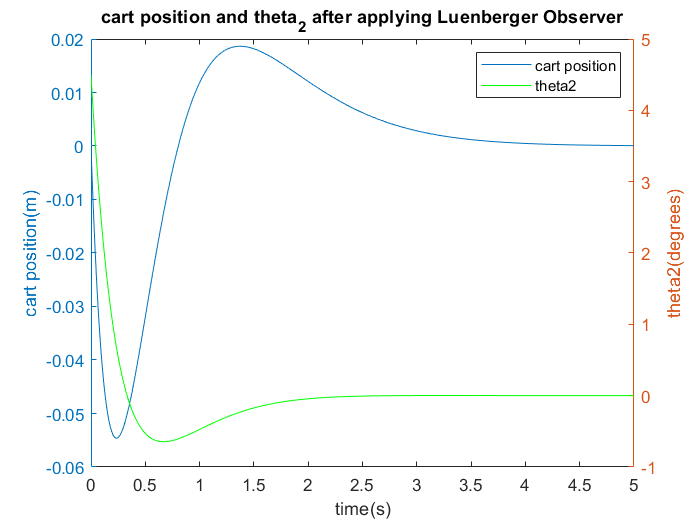

Ac = A - L*C;
Bc = [0;0;0;0;0;0];
Cc = C;
Dc = 0;
closed_loop_sys = ss(Ac,Bc,Cc,Dc);
[y,t,~] = lsim(closed_loop_sys,u,t,X0);
figure;
yyaxis left
plot(t,y(:,1))
ylabel('cart position(m)')
yyaxis right
plot(t,y(:,2)*(180/pi),'g')
ylabel('theta2(degrees)')
title('cart position and theta_2 after applying Luenberger Observer')
xlabel('time(s)')
legend('cart position','theta2')

###         iv) Applying Luenberger gain for cart position, angular position of mass 1 and 2

%cart position X, theta1 and theta2
C = [1 0 0 0 0 0;0 0 1 0 0 0;0 0 0 0 1 0 ];
L = place(A',C',new_poles)';
Ac = A - L*C;
luenberger_gain=L

luenberger_gain =     5.5367    0.1418   -0.0000
    7.6284   -0.5970   -0.9800
    0.1503    5.2633   -0.0000
    0.4069    6.3526   -0.0490
   -0.0000   -0.0000    4.4200
   -0.0000   -0.0980    3.7940


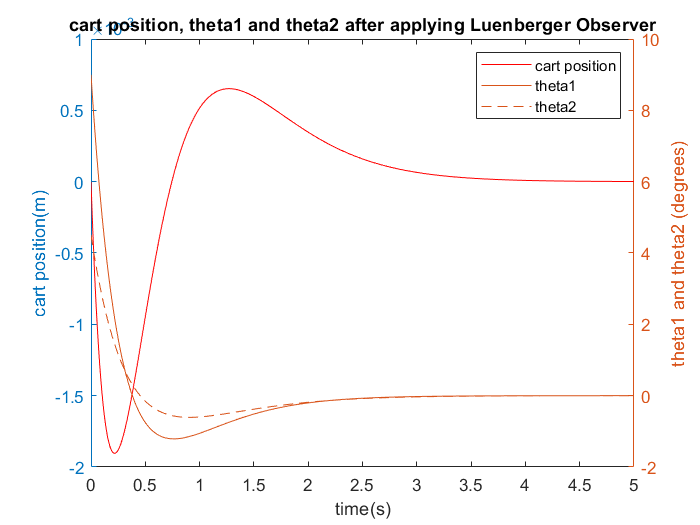

Bc = [0;0;0;0;0;0];
Cc = C;
Dc = 0;
closed_loop_sys = ss(Ac,Bc,Cc,Dc);
[y,t,~] = lsim(closed_loop_sys,u,t,X0);

figure;
yyaxis left;
plot(t,y(:,1),'red')
ylabel('cart position(m)');
yyaxis right;
plot(t,[y(:,2),y(:,3)]*(180/pi))
title('cart position, theta1 and theta2 after applying Luenberger Observer');
xlabel('time(s)');
ylabel('theta1 and theta2 (degrees)')
legend('cart position','theta1','theta2')